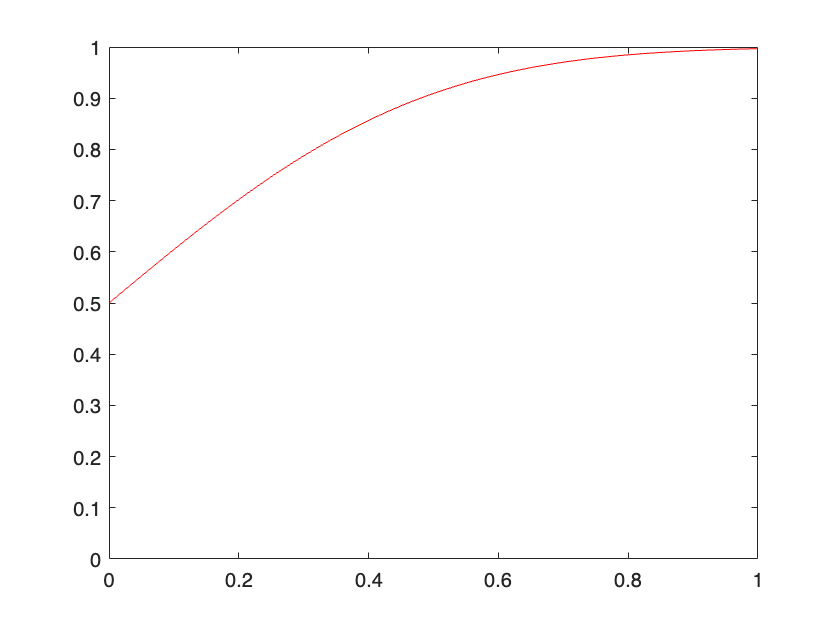

x = 0 : 0.01: 1;

P_D = 1 - 0.5 .* (normcdf(0.5-3.*x)+normcdf(-0.5-3.*x));
plot(x, P_D, 'r'), axis([0 1 0 1])

load hw2dat
% Metal objects: H1
% Wooden objects: H0

% Col 1: data from H0
% Col 2: data from H1
% Col 3: source info for test data
% Col 4: test data
H_0 = hw2dat(:, 1);
H_1 = hw2dat(:, 2);
S_info = hw2dat(:, 3);
test = hw2dat(:, 4);

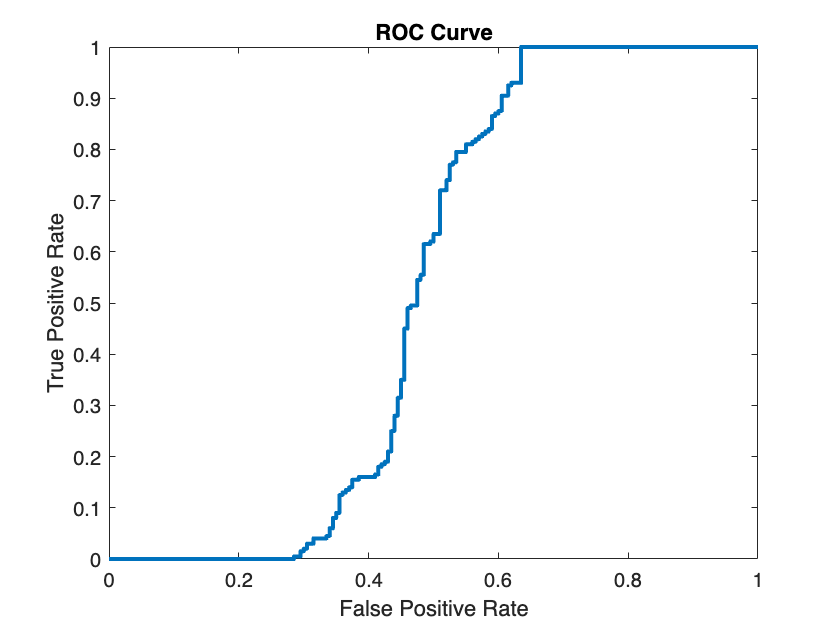

% Select only the first 200 points of H1 and H0
H1 = H_1(1:200);
H0 = H_0(1:200);

% Calculate true positive rate (TPR) and false positive rate (FPR)
[TPR, FPR] = perfcurve([ones(length(H1),1); zeros(length(H0),1)], [H1; H0], 1);

% Plot ROC curve
plot(FPR, TPR, 'LineWidth', 2);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curve');